# Lab 4

**Members:  Hazika Farooq & Syed Mustafa**

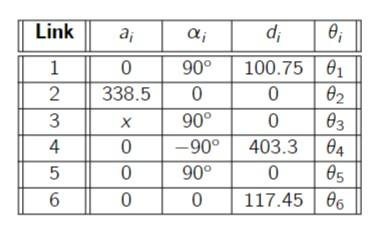

 syms('theta_5','theta_4','theta_6', 'alpha_6','alpha_5','alpha_4','a_4','a_5','a_6' ,'d_4','d_5','d_6' )
theta_5+theta_4+theta_6+ alpha_6+alpha_5+alpha_4+a_4+a_5+a_6 +d_4+d_5+d_6

$$ans = a_{4}+a_{5}+a_{6}+\alpha_{4}+\alpha_{5}+\alpha_{6}+d_{4}+d_{5}+d_{6}+\theta_{4}+\theta_{5}+\theta_{6}$$

theta = [theta_4,theta_5,theta_6];
alpha = [-pi/2,pi/2 ,0]

alpha =    -1.5708    1.5708         0


a = [0 0 0];
d = [403.3 0 117.45];
T = DH(theta(1), alpha(1),a(1),d(1))

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\frac{4967757600021511\,\sin\left(\theta_{4}\right)}{81129638414606681695789005144064} & -\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & \frac{4967757600021511\,\cos\left(\theta_{4}\right)}{81129638414606681695789005144064} & \cos\left(\theta_{4}\right) & 0\\ 0 & -1 & \frac{4967757600021511}{81129638414606681695789005144064} & \frac{4033}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

for i = 2:3
    
    T = ( T * DH(theta(i), alpha(i),a(i),d(i)));
end
simplify(vpa(T,2))

T(1,1)

$$ans = \cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{180}\right)$$

simplify(T(1,1))

$$ans = \cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{180}\right)$$

x = cos(theta_4)*cos(theta_5)*cos(theta_6)-sin(theta_4)*sin(theta_6)

$$x = \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)$$

simplify(x)

$$ans = \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)$$

## Task 4.1

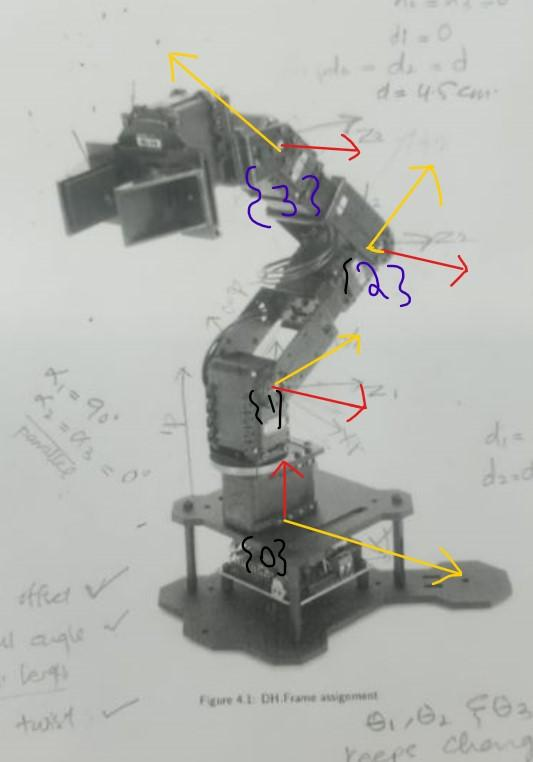

Yellow = x axis

Red = Z axis

## Task 4.2

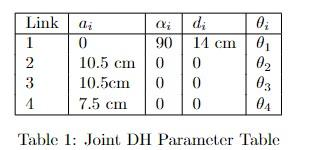

## Task 4.3

syms('theta_1')
syms('theta_2')
syms('theta_3')
syms('theta_4')


alpha_1 =90;
d_1=14;
a_1=0;

alpha_2 =0;
d_2=0;
a_2 = 10.5;

alpha_3 =0;
d_3=0;
a_3=10.5;

alpha_4 =0;
d_4=0;
a_4 =7.5;

T01 = [cosd(theta_1),  -sind(theta_1)*cosd(alpha_1), sind(theta_1)*sind(alpha_1) a_1*cosd(theta_1);
    sind(theta_1), cosd(theta_1)*cosd(alpha_1), -cosd(theta_1)*sind(alpha_1), a_1*sind(theta_1);
    0, sind(alpha_1), cosd(alpha_1), d_1;
    0, 0 , 0, 1];

T02 = [cosd(theta_2),  -sind(theta_2)*cosd(alpha_2), sind(theta_2)*sind(alpha_2) a_2*cosd(theta_2);
    sind(theta_2), cosd(theta_2)*cosd(alpha_2), -cosd(theta_2)*sind(alpha_2), a_2*sind(theta_2);
    0, sind(alpha_2), cosd(alpha_2), d_2;
    0, 0 , 0, 1];

T03 = [cosd(theta_3),  -sind(theta_3)*cosd(alpha_3), sind(theta_3)*sind(alpha_3) a_3*cosd(theta_3);
    sind(theta_3), cosd(theta_3)*cosd(alpha_3), -cosd(theta_3)*sind(alpha_3), a_3*sind(theta_3);
    0, sind(alpha_3), cosd(alpha_3), d_3;
    0, 0 , 0, 1];

T04= [cosd(theta_4),  -sind(theta_4)*cosd(alpha_4), sind(theta_4)*sind(alpha_4) a_4*cosd(theta_4);
    sind(theta_4), cosd(theta_4)*cosd(alpha_4), -cosd(theta_4)*sind(alpha_4), a_4*sind(theta_4);
    0, sind(alpha_4), cosd(alpha_4), d_4;
    0, 0 , 0, 1];


T=simplify(T01*T02*T03*T04 )

$$T = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\sigma_{5} & -\sigma_{3}\,\sigma_{1} & \sigma_{2} & \frac{3\,\sigma_{3}\,\sigma_{4}}{2}\\ \sigma_{2}\,\sigma_{5} & -\sigma_{2}\,\sigma_{1} & -\sigma_{3} & \frac{3\,\sigma_{2}\,\sigma_{4}}{2}\\ \sigma_{1} & \sigma_{5} & 0 & \frac{21\,\sin\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)}{2}+\frac{21\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)}{2}+\frac{15\,\sigma_{1}}{2}+14\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{4}=7\,\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)+7\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)+5\,\sigma_{5}\\ \sigma_{5}=\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{180}\right) \end{array}$$

## Task 4.4

Note: The angle in this function is taken strictly in degrees

## Task 4.5

The given code was made into a function to allow for reussability 

joint_angles = [pi/2, 0, 0, 0] 

joint_angles =     1.5708         0         0         0


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


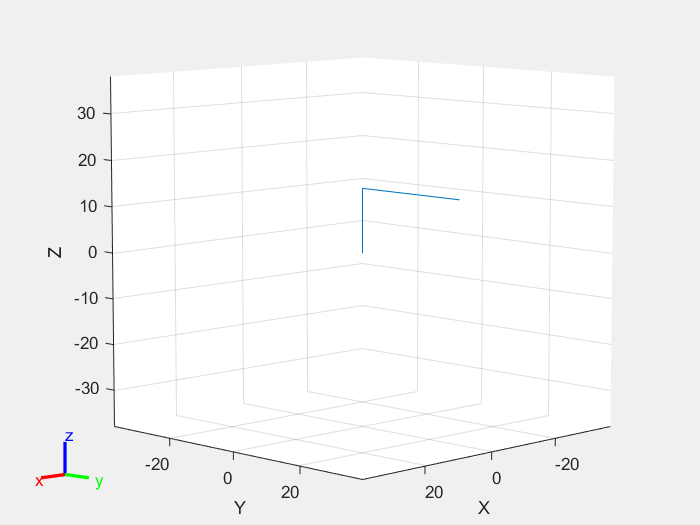

The position of end-effector is:
X: 1.7451e-15
Y: 28.5
Z: 14
 
R: 


ans =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
         0    1.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 0 degrees.


pincherModel(joint_angles)

joint_angles = joint_angles * 180/pi

joint_angles =     90     0     0     0


findPincher(joint_angles(1),joint_angles(2),joint_angles(3),joint_angles(4))

ans = 0

joint_angles = [pi/2, 0, 0, pi/2] 

joint_angles =     1.5708         0         0    1.5708


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


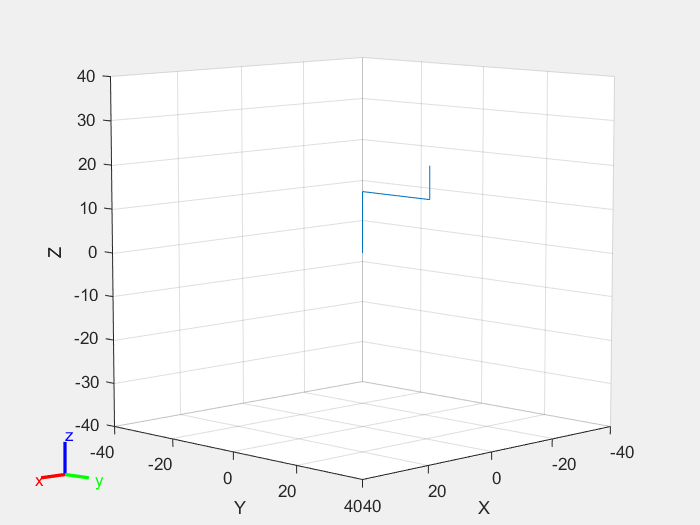

The position of end-effector is:
X: 8.2664e-16
Y: 21
Z: 21.5
 
R: 


ans =    -0.0000   -0.0000    1.0000
    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 90 degrees.


pincherModel(joint_angles)

joint_angles = joint_angles * 180/pi

joint_angles =     90     0     0    90


findPincher(joint_angles(1),joint_angles(2),joint_angles(3),joint_angles(4))

ans = 0

joint_angles = [pi/2, 0, pi/4, pi/2] 

joint_angles =     1.5708         0    0.7854    1.5708


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


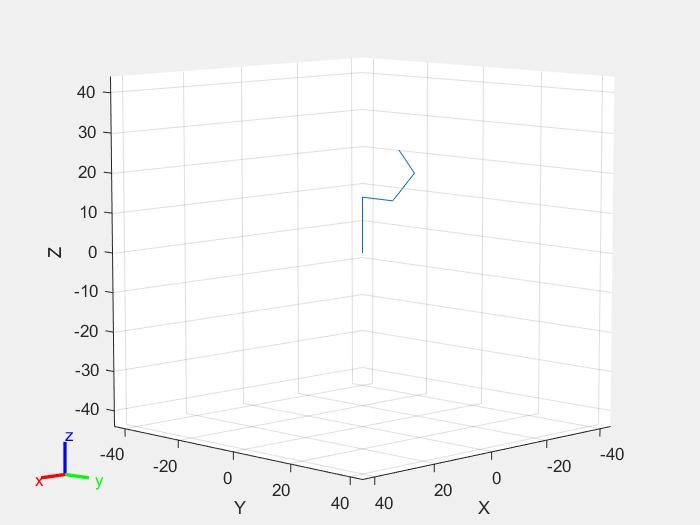

The position of end-effector is:
X: -6.5275e-18
Y: 12.6213
Z: 26.7279
 
R: 


ans =    -0.0000   -0.0000    1.0000
   -0.7071   -0.7071   -0.0000
    0.7071   -0.7071    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 135 degrees.


pincherModel(joint_angles)

joint_angles = joint_angles * 180/pi

joint_angles =     90     0    45    90


findPincher(joint_angles(1),joint_angles(2),joint_angles(3),joint_angles(4))

ans = 0

joint_angles = [pi/2, pi/2, pi/2, pi/2] 

joint_angles =     1.5708    1.5708    1.5708    1.5708


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


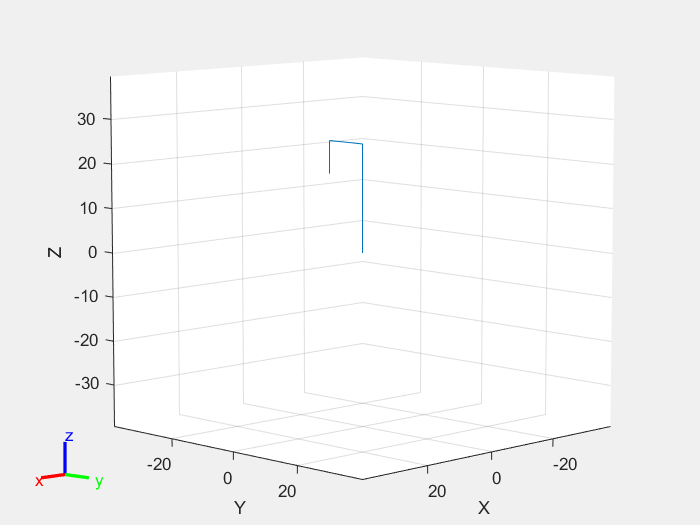

The position of end-effector is:
X: -8.2664e-16
Y: -10.5
Z: 17
 
R: 


ans =     0.0000    0.0000    1.0000
   -0.0000    1.0000   -0.0000
   -1.0000   -0.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: -90 degrees.


pincherModel(joint_angles)

joint_angles = joint_angles * 180/pi

joint_angles =     90    90    90    90


findPincher(joint_angles(1),joint_angles(2),joint_angles(3),joint_angles(4))

ans = 0

## Task 4.6

## 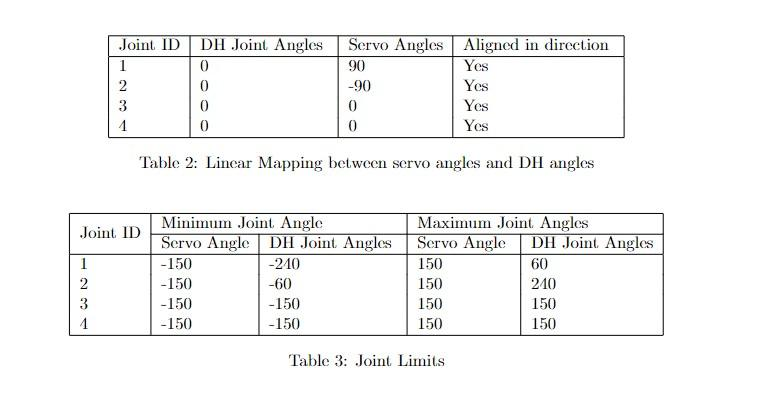

## Task 4.7

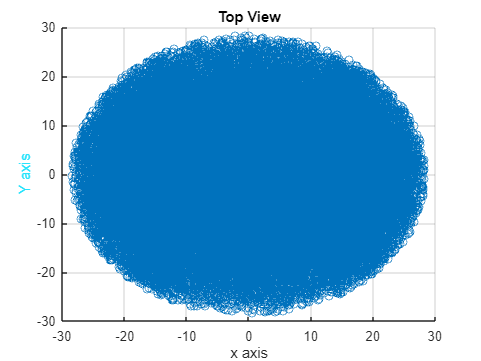

%% Task 4.7
N = 100000;
theta = zeros(4,N);
Angles = [-240 60; -60 240; -150 150; -150 150];
theta = Angles(:,1) + (Angles(:,2)-Angles(:,1)).* rand(4, N);pos = zeros(3, N);
index = 1;
for thet = theta
  [x,y,z,R] = findPincher(thet(1),thet(2),thet(3),thet(4));
  pos(:,index) = [x,y,z];
  index = index + 1;
  
end
figure;
scatter3(pos(1,:),pos(2,:),pos(3,:))
xlabel('x axis'); ylabel('Y axis', 'Color',[0.15 0.89 0.99]);zlabel('Z axis');
view(0,90)
title('Top View')

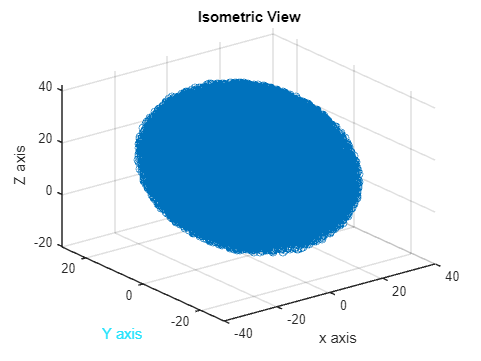

figure;
scatter3(pos(1,:),pos(2,:),pos(3,:))
title('Isometric View')
xlabel('x axis'); ylabel('Y axis', 'Color',[0.15 0.89 0.99]);zlabel('Z axis');

## Task 4.8

setPosition([0 0 0 0])

serPort COM10is in use.   Closing it.


checksum fail: is 61, should be 93


i = 4

 
arb = 
Arbotix chain on serPort COM10 (open)
 5 servos in chain                   


ans = 0

## Task 4.9

thetas = zeros(5,4);
thetas(1,:) = [pi/2, 0, 0, 0] ;
thetas(2,:) = [pi/2, pi, 0, 0] ;
thetas(3,:) = [-pi/2, -pi/2, -3*pi/2, 0] ;
thetas(4,:) = [pi/2, 0, 0, +pi/2] ;
thetas(5,:) = [pi/2, 0, 0, -pi/2] ;
calculated = zeros(5,3)

calculated =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x = 28.4893

y = 0.7812

z = 14

R =     0.9996         0    0.0274
    0.0274         0   -0.9996
         0    1.0000         0


caluclated =    28.4893    0.7812   14.0000


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


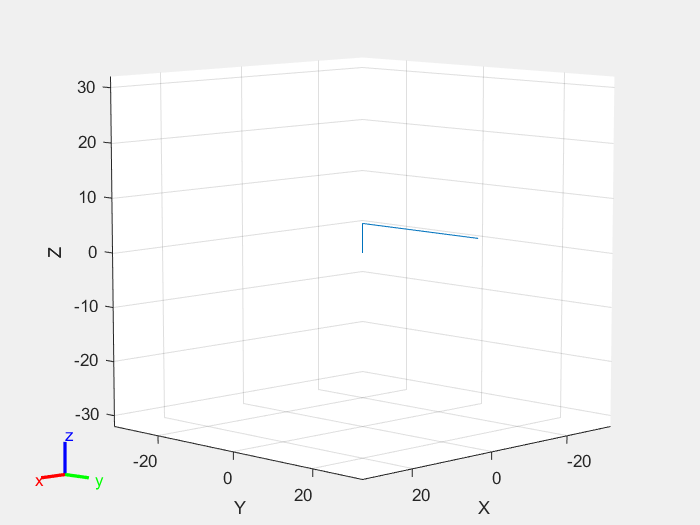

The position of end-effector is:
X: 1.7451e-15
Y: 28.5
Z: 5.4
 
R: 


ans =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
         0    1.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 0 degrees.


1.5708           0           0           0


run


x = 28.4465

y = 0.7801

z = 15.5619

R =     0.9981   -0.0548    0.0274
    0.0274   -0.0015   -0.9996
    0.0548    0.9985         0


caluclated =    28.4893    0.7812   14.0000
   28.4465    0.7801   15.5619


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


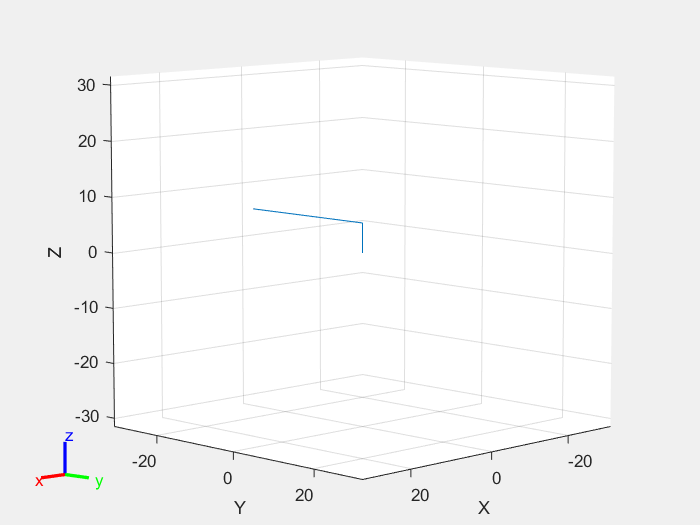

The position of end-effector is:
X: -1.7451e-15
Y: -28.5
Z: 5.4
 
R: 


ans =    -0.0000    0.0000    1.0000
   -1.0000   -0.0000   -0.0000
    0.0000   -1.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 180 degrees.


1.5708      3.1416           0           0


run


x = 28.3773

y = -0.7782

z = 11.7422

R =     0.9936    0.1094   -0.0274
   -0.0272   -0.0030   -0.9996
   -0.1094    0.9940         0


caluclated =    28.4893    0.7812   14.0000
   28.4465    0.7801   15.5619
   28.3773   -0.7782   11.7422


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


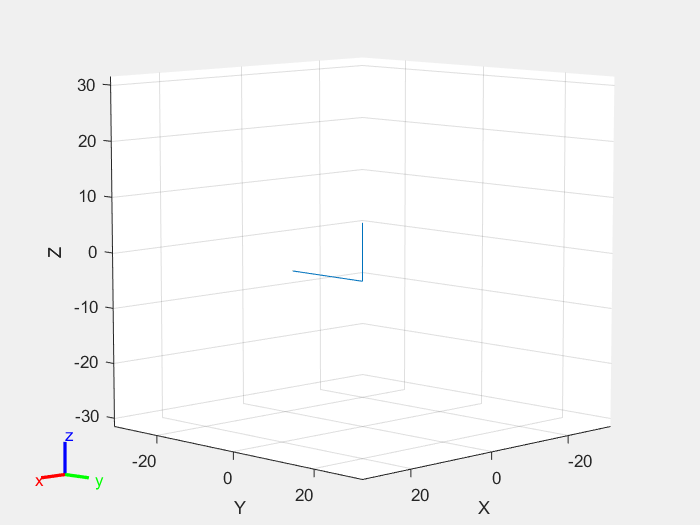

The position of end-effector is:
X: 4.5924e-16
Y: -18
Z: -5.1
 
R: 


ans =     0.0000    0.0000   -1.0000
   -1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 1.4033e-14 degrees.


-1.5708     -1.5708     -4.7124           0


run


x = 28.4865

y = 0.7812

z = 14.2056

R =     0.9992   -0.0274    0.0274
    0.0274   -0.0008   -0.9996
    0.0274    0.9996         0


caluclated =    28.4893    0.7812   14.0000
   28.4465    0.7801   15.5619
   28.3773   -0.7782   11.7422
   28.4865    0.7812   14.2056


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


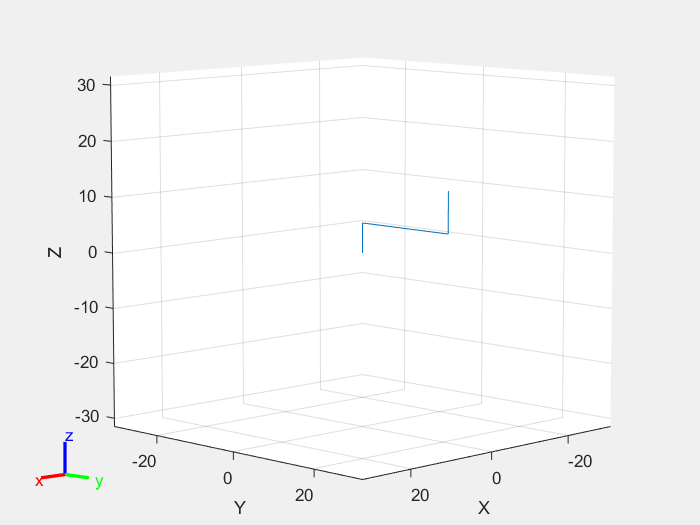

The position of end-effector is:
X: 8.2664e-16
Y: 21
Z: 12.9
 
R: 


ans =    -0.0000   -0.0000    1.0000
    0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: 90 degrees.


1.5708           0           0      1.5708


run


x = 28.4865

y = 0.7812

z = 13.7944

R =     0.9992    0.0274    0.0274
    0.0274    0.0008   -0.9996
   -0.0274    0.9996         0


caluclated =    28.4893    0.7812   14.0000
   28.4465    0.7801   15.5619
   28.3773   -0.7782   11.7422
   28.4865    0.7812   14.2056
   28.4865    0.7812   13.7944


--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


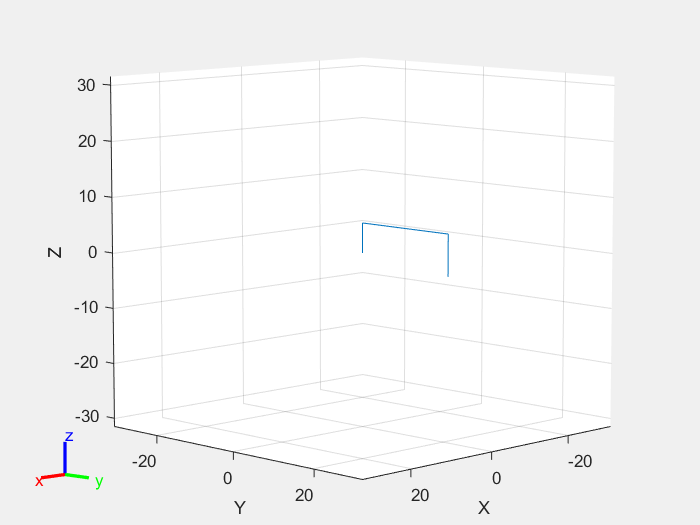

The position of end-effector is:
X: 1.7451e-15
Y: 21
Z: -2.1
 
R: 


ans =     0.0000    0.0000    1.0000
    0.0000    1.0000   -0.0000
   -1.0000    0.0000    0.0000


 
The orientation angle is given with respect to the x-axis of joint 2:
Angle: -90 degrees.


1.5708           0           0     -1.5708


run


for i=1:5
    [x, y, z, R] = findPincher(thetas(i,1), ...
    thetas(i,2), ...
    thetas(i,3), ...
    thetas(i,4))
    caluclated(i,:) = [x y z]
    pincherModel([thetas(i,1), ...
    thetas(i,2), ...
    thetas(i,3), ...
    thetas(i,4)])
    disp(num2str(thetas(i,:)))
    disp('run')
end

i = 3;
% pincherModel([thetas(i,1), ...
%     thetas(i,2), ...
%     thetas(i,3), ...
%     thetas(i,4)])
% thetas = thetas * 180/pi
% setPosition([thetas(i,1), ...
%     thetas(i,2), ...
%     thetas(i,3), ...
%     thetas(i,4)] ...
%     )

caluclated

caluclated =    28.4893    0.7812   14.0000
   28.4465    0.7801   15.5619
   28.3773   -0.7782   11.7422
   28.4865    0.7812   14.2056
   28.4865    0.7812   13.7944


Measured

Measured =    29.1000    1.5000   14.4000
   29.0000    0.8000   16.3000
   29.1000   -0.2000   12.7000
   28.7000    0.8000   15.0000
   29.0000    1.7000   13.9000


Error = abs(caluclated - Measured)

Error =     0.6107    0.7188    0.4000
    0.5535    0.0199    0.7381
    0.7227    0.5782    0.9578
    0.2135    0.0188    0.7944
    0.5135    0.9188    0.1056


euclidean_error = sqrt(Error(:,1).^2+Error(:,2).^2+Error(:,3).^2)

euclidean_error =     1.0245
    0.9228
    1.3319
    0.8228
    1.0579
